# **Extracting useful signals from flawed sensor data: developing hybrid data-driven approaches with physical factors - Code Implementation **

**Cheng Yang (a), Glen T. Daigger (a), Evangelia Belia (b), B. Kerkez (a)**

**(a)** Civil and Environmental Engineering, University of Michigan, 2350 Hayward St, G.G. Brown Building, Ann Arbor, MI 48109, US  

**(b)** Primodal Inc., 145 Rue Aberdeen, Quebec City, Quebec, CA  

## About the research data

        The sensor signals in this study were $BOD_5$ concentration measurements of plant influent by a LiquID™ Station unit (ZAPS Technologies, LLC.), with 720 measurements per day. The dataset covered 688 days (495,360 measurements). Daily composite $BOD_5$  samples were also collected and analysed (688 days).  

        While the authors are not allowed to share meta-information of sensor data, we decided to anonymize all meta information but provided a data Matrix:

- **xBOD.m** - the data matrix storing the sensor signals used in this study. Preprossing was already done (replacing zeros with NaN), and the signal steam has been reshaped into a 688 by 720 matrix, where each row is an independent day and each column stands a measure at a time stamp starting from 6 am, with an interval of 2 minutes.    

- **data_label.m** - the label used in the section **Quality Classification**. 

### Import data 

clear; 
close all;

load('xBOD.mat');
load("data_label.mat");

## Figure 1 - Creation  

The indice of the days used for these plots are: 

(a) 27 ; (b) 3; (c) 10; (d) 65; (e) 50 ; (f) 73  

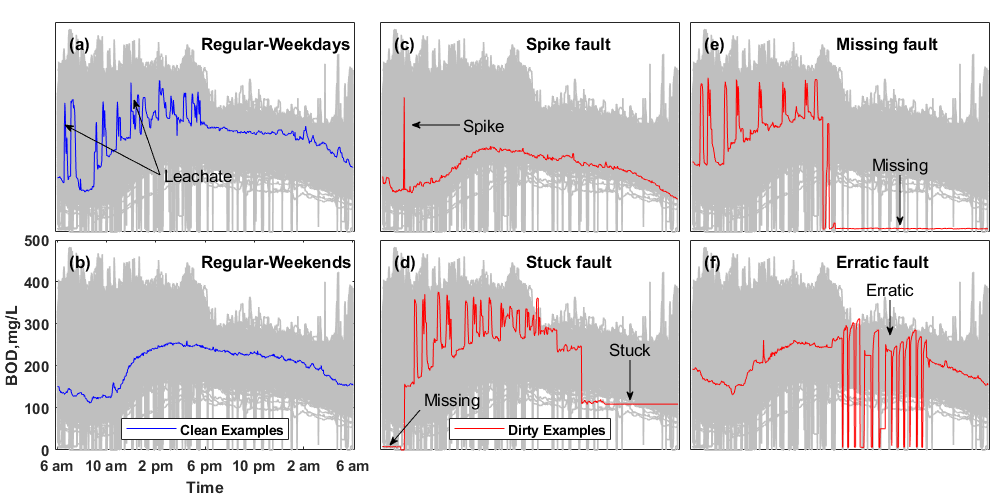

figure('position',[100 100 800 400],'Units','centimeters');
ax1 = axes('position',[0.055,0.535,0.30,0.42]); % Weekdays 
L1 = plot(xBOD(~data_label,:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plt1= plot(xBOD(27,:),'-b');
text(gca,30,450,'(a)',"FontWeight","bold");
text(gca,350,450,'Regular-Weekdays',"FontWeight","bold");

hold off;

ax2 = axes('position',[0.38,0.535,0.3,0.42]);  %spike 
L2 = plot(xBOD(~data_label,:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plot(xBOD(10,:),'-r');
text(gca,350,450,'Spike fault',"FontWeight","bold");
text(gca,30,450,'(c)',"FontWeight","bold");
hold off;

ax3 = axes('position',[0.69,0.535,0.3,0.42]); % Missing 
L3 = plot(xBOD(~data_label,:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plot(xBOD(50,:),'-r');
text(gca,350,450,'Missing fault',"FontWeight","bold");
text(gca,30,450,'(e)',"FontWeight","bold");
hold off;

ax4 = axes('position',[0.055,0.10,0.3,0.42]); % Weekend 
L4 = plot(xBOD(~data_label,:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'XTick',linspace(0,720,7),'XTickLabel',{'6 am','10 am','2 pm','6 pm','10 pm','2 am','6 am'},...
    'FontWeight','bold');
xlabel('Time');
ylabel('BOD,mg/L');
hold on;
plot(xBOD(571,:),'-b');
text(gca,350,450,'Regular-Weekends',"FontWeight","bold");
text(gca,30,450,'(b)',"FontWeight","bold");
hold off;

ax5 = axes('position',[0.38,0.10,0.3,0.42]); % stuck 
L5 = plot(xBOD(~data_label,:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plt2= plot(xBOD(65,:),'-r');
text(gca,350,450,'Stuck fault',"FontWeight","bold");
text(gca,30,450,'(d)',"FontWeight","bold");

hold off;

ax6 = axes('position',[0.69,0.10,0.3,0.42]); % erratic 
L6 = plot(xBOD(~data_label,:)','color',[0.75 0.75 0.75],'LineWidth',1);
ylim([0,500]);
xlim([-5,725]);
set(gca,'YTick',[],'XTick',[]);
hold on;
plot(xBOD(73,:),'-r');
text(gca,350,450,'Erratic fault',"FontWeight","bold");
text(gca,30,450,'(f)',"FontWeight","bold");
hold off;

legend(ax4,[plt1],'Clean Examples','location','south','FontWeight','bold');
legend(ax5,[plt2],'Dirty Examples','location','south','FontWeight','bold');
annotation('textarrow',[0.16 0.065],[0.65 0.75],'String','Leachate','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
annotation('arrow',[0.16 0.134],[0.65 0.8],'HeadLength',5,"HeadWidth",5);
annotation('textarrow',[0.46 0.412],[0.75 0.75],'String','Spike','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
annotation('textarrow',[0.9 0.9],[0.65 0.55],'String','Missing','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
annotation('textarrow',[0.63 0.63],[0.28 0.2],'String','Stuck','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
annotation('textarrow',[0.42 0.39],[0.18 0.11],'String','Missing','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);
annotation('textarrow',[0.89 0.89],[0.4 0.33],'String','Erratic','HorizontalAlignment',"center",'HeadLength',5,"HeadWidth",5);

clearvars -except data_label xBOD;

## Section 1: Pattern Separation 

### Failutre of traditional pattern separation algorithms (OLS + Lowpass filter + PCA)

***Oridnary Least Squares - using Fourier Series to approxiamte diurnal pattern ***

*An one-day series could be approximated as the sum of diurnal pattern and residuals, as *$y=\Gamma x+\epsilon \;$*, where the *$\Gamma x\;$*is the diurnal pattern, and *$\epsilon$* is the residuals. The formula could be further reduced into the matrix form as *


$$y=\Gamma x\;+\;\epsilon$$
 

*In the ordinary least squares, the objective is to mimimize the difference between *$y$* and *$\Gamma x\;$*, therefore, the loss function could be written as *


$$\hat{x} =\;\underset{x}{\arg \;\min } \;\left\|y-\Gamma x\right\|{\;}_2^{2\;} \;\;$$


*The diurnal term was approximated as the 3rd-order Fourier series,  *$y_i =x_1 +\sum_{k=1}^3 x_{2i\;} \cos \left(k\cdot w\cdot \;i\right)+\sum_{k=1}^3 x_{2\;i+1\;} \sin \left(k\cdot w\cdot \;i\right)\;+\epsilon_i$*, while in matrix form as *

$\begin{array}{l}
\left\lbrack \begin{array}{c}
y_1 \\
\vdots \\
y_i \\
\vdots \\
y_{720} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccccc}
1 & \cos \left(1\cdot w\cdot 1\right) & \sin \left(1\cdot w\cdot 1\right) & \cos \left(2\cdot w\cdot 1\right) & \sin \left(2\cdot w\cdot 1\right) & \cos \left(3\cdot w\cdot 1\right) & \sin \left(3\cdot w\cdot 1\right)\\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots \\
1 & \cos \left(1\cdot w\cdot i\right) & \sin \left(1\cdot w\cdot i\right) & \cos \left(2\cdot w\cdot i\right) & \sin \left(2\cdot w\cdot i\right) & \cos \left(3\cdot w\cdot i\right) & \sin \left(3\cdot w\cdot i\right)\\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots \\
1 & \cos \left(1\cdot w\cdot 720\right) & \sin \left(1\cdot w\cdot 720\right) & \cos \left(2\cdot w\cdot 720\right) & \sin \left(2\cdot w\cdot 720\right) & \sin \left(3\cdot w\cdot 720\right) & \sin \left(3\cdot w\cdot 720\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 \\
x_6 \\
x_7 
\end{array}\right\rbrack \\
\;
\end{array}$* + *$\left\lbrack \begin{array}{c}
\epsilon_1 \\
\vdots \\
\epsilon_i \\
\vdots \\
\epsilon_{720} 
\end{array}\right\rbrack \Rightarrow y=\Gamma x+\epsilon$ 

#### **Low pass filter**

filter= designfilt('lowpassiir','PassbandFrequency',2.5,...
    'StopbandFrequency',2.7,'PassbandRipple',0.05,...
    'StopbandAttenuation',60,'SampleRate',720,'DesignMethod','ellip');

#### Principal component analysis (Singular Value Decomposition with lower rank approximation) 

Using the first 5 principal components to approximate the diurnal patterns. Rank = 5.  

%% PCA 
[U,S,V] = svd(xBOD,'econ');
S(5:end,5:end) =0;
xBOD_pca = U*S*V';
clearvars -except data_label xBOD filter xBOD_pca;

#### Failure results presentation 

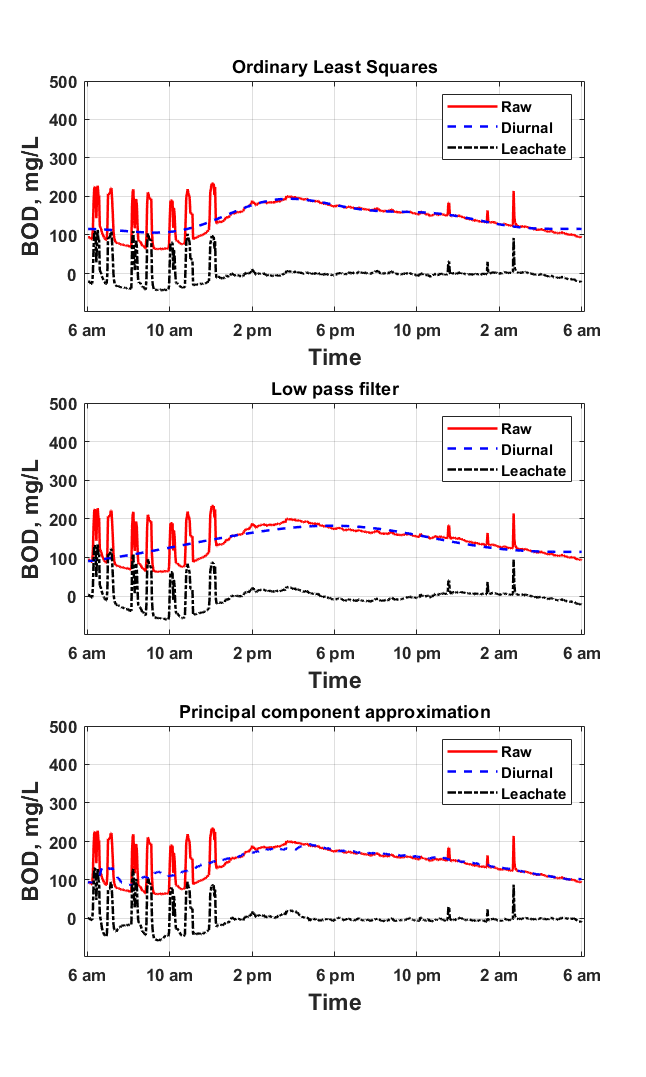

% Choose EXAMPLE idX
idx = 241; 

% OLS method 
% Set-up global constants  
d = 3;
ols_y = xBOD(idx,:)';
t = 1:length(ols_y);
w= 2*pi/720;
ols_y = xBOD(idx,:)';
ols_x = zeros(length(ols_y),2*d+1);
for  i = 1:d   
    ols_x(:,2*i) = cos(i*w*t);   
    ols_x(:,2*i+1) = sin(i*w*t);
end
ols_x(:,1) = ones(length(ols_y),1);
ols_beta = ols_x \ ols_y;



% plot the results 
figure('position',[0 0 600 1000],'Units','centimeters');

% OLS 
subplot(3,1,1)
ax1 = singleTSplot(ols_y);
hold on;
ax2 = plot(ols_x*ols_beta);
ax3 = plot(ols_y - ols_x*ols_beta);
set(ax1,'color','red','LineWidth',1.5);
set(ax2,'color','blue','LineWidth',1.5,'LineStyle','--');
set(ax3,'color','black','LineWidth',1.5,'LineStyle','-.');
hold off;
legend('Raw','Diurnal','Leachate');    
title('Ordinary Least Squares')

% low pass filter  
subplot(3,1,2)
ax1 = singleTSplot(xBOD(idx,:));
hold on;

filter_y = filtfilt(filter,xBOD(idx,:)');
ax2 = plot(filter_y);
ax3 = plot(xBOD(idx,:)' - filter_y);

set(ax1,'color','red','LineWidth',1.5);
set(ax2,'color','blue','LineWidth',1.5,'LineStyle','--');
set(ax3,'color','black','LineWidth',1.5,'LineStyle','-.');
title('Low pass filter')
hold off;
legend('Raw','Diurnal','Leachate');  
% PCA/SVD  
subplot(3,1,3)
ax1 = singleTSplot(xBOD(idx,:));
hold on;
ax2 = plot(xBOD_pca(idx,:));
ax3 = plot(xBOD(idx,:) - xBOD_pca(idx,:));

set(ax1,'color','red','LineWidth',1.5);
set(ax2,'color','blue','LineWidth',1.5,'LineStyle','--');
set(ax3,'color','black','LineWidth',1.5,'LineStyle','-.');
title('Principal component approximation')
hold off;
legend('Raw','Diurnal','Leachate');  

clear ax1 ax2 ax3 d i idx t w;

### Customized algorithms coupled with physcial factors - regularized least squares 

**Important Note:**

- Processing through the whole daily profiles takes more than 3 hours, therefore, processed results are already uploaded in this repo for time saving.

- The implementation of the pattern separation process can be tracked in:  seperatePatterScript.m. Details about its relating functions such as seperatePattern,m, hhlsngd.m, hubhin.m and dhubhin could be found in README.md 

**Math behind: **

**Regularized Least Squares - Shifted Huber-Hinge Regularization( Non-negtaive Regularization)**

An one-day series could be approximated as the sum of diurnal pattern, leachate and residuals, as $y=\Gamma x+s+\epsilon \;$, where the $\Gamma x\;$is the diurnal pattern, the $s$ is the leachate pattern and $\epsilon$ is the residuals. The formula could be further reduced into the matrix form as 


$$y=\Gamma x+\textrm{Is}+\epsilon =\left\lbrack \begin{array}{cc}
\Gamma \; & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
s
\end{array}\right\rbrack +\epsilon =\tilde{A} \;\tilde{x} +\epsilon$$
 

Where $I$ is the Identity matrix, and $\tilde{A} \;$is the horizontal concatenation of $\Gamma$ and $I$, and $\tilde{x}$ is the vertical concatenation of $x$ and $s$. Simliarly, this problem has been transfromed  into 

$\hat{x} =\;\underset{x}{\arg \;\min } \;\left\|y-\Gamma x-s\right\|{\;}_2^{2\;} =\underset{\tilde{x} }{\arg \;\min } \;\left\|y-\tilde{A} \tilde{x} \right\|{\;}_2^2 \;$. 

This time, regularization was changed and was applied on the leachate term, $s$,  as 


$$\hat{x} =\;\underset{x}{\arg \;\min } \;{\left\|y-\Gamma x-s\;\right\|}_2^2 \;+\lambda \cdot h\left(s\right)\;$$


The lechate pattern is regularized by the shifted huber-hinger error function$\;h\left(x\right)$, which penalizes the negative part. The shifted huber-hinger error function is: $h\left(x\right)=\left\lbrace \begin{array}{cc}
-x-\frac{\;\delta }{2} & x\le -\delta \\
\;\;\frac{1}{2\delta }x^2  & -\delta <x\le 0\;\\
0 & x>0
\end{array}\right.\;$ and its derivative is:   $\frac{\mathrm{d}}{\mathrm{d}x}h\left(x\right)=\left\lbrace \begin{array}{cc}
-1 & x\le -\delta \\
\;\;\frac{1}{\delta }x & -\delta <x\le 0\;\\
0 & x>0
\end{array}\;\right.$  .The shape of these two functions are displayed below. 

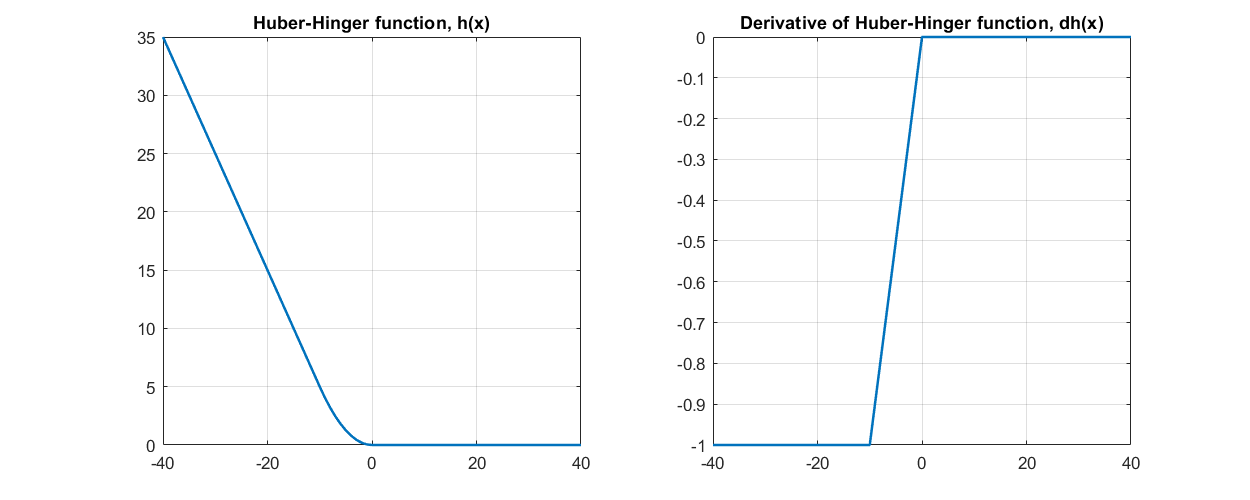

% plotting hubhin() and dhubhin() 
figure('position',[0 0 1000 400],'Units','centimeters');
subplot(1,2,1);
plot(-40:40,hubhin(-40:40,10),'-','LineWidth',1.5);
grid on;
title('Huber-Hinger function, h(x)')
subplot(1,2,2);
plot(-40:40,dhubhin(-40:40,10),'-','LineWidth',1.5);
grid on;
title('Derivative of Huber-Hinger function, dh(x)')

% Load results after separation 
clearvars -except data_label xBOD filter;
load xDiurnal.mat;
load xLeachate.mat;

### Figure 3 - Creation - the index used in paper is 1 

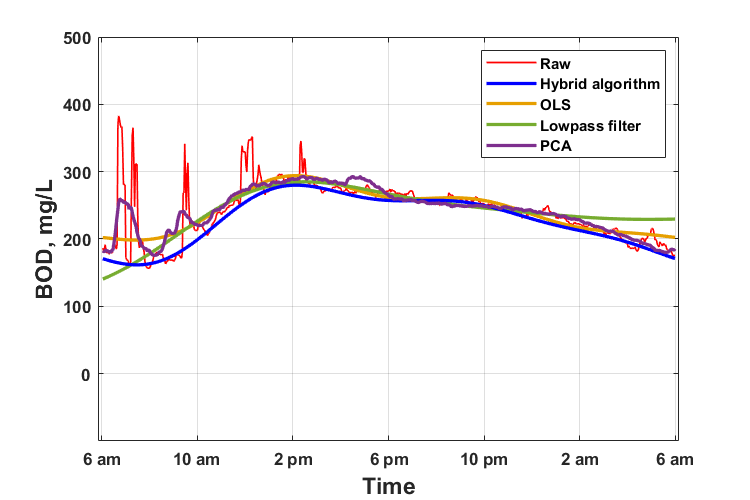

% Compare the result of above three methods 
% Choose EXAMPLE idX
idx = 440; 

% OLS method 
% Set-up global constants  
d = 3;
ols_y = xBOD(idx,:)';
t = 1:length(ols_y);
w= 2*pi/720;
ols_y = xBOD(idx,:)';
ols_x = zeros(length(ols_y),2*d+1);
for  i = 1:d   
    ols_x(:,2*i) = cos(i*w*t);   
    ols_x(:,2*i+1) = sin(i*w*t);
end
ols_x(:,1) = ones(length(ols_y),1);
ols_beta = ols_x \ ols_y;

figure('position',[0 0 600 400],'Units','points');
ax1 = singleTSplot(ols_y);
hold on;
ax2 = plot(ols_x*ols_beta);
% design a lowpass filter for it
filter_y = filtfilt(filter,xBOD(idx,:));
ax3 = plot(filter_y);
ax4 = plot(xDiurnal(idx,:));

%% PCA 
[U,S,V] = svd(xBOD,'econ');
S(5:end,5:end) =0;
xBOD_approx = U*S*V';
ax5 = plot(xBOD_approx(idx,:));

set(ax1,'color','red','LineWidth',1);
set(ax2,'color',[230 159 0 10]/255,'LineWidth',2,'LineStyle','-');
set(ax3,'color',[0.4660 0.6740 0.1880],'LineWidth',2,'LineStyle','-');
set(ax4,'color','blue','LineWidth',2,'LineStyle','-');
set(ax5,'color',[0.4940 0.1840 0.5560],'LineWidth',2,'LineStyle','-');
legend([ax1 ax4 ax2 ax3 ax5],'Raw','Hybrid algorithm','OLS','Lowpass filter', 'PCA');



% X&Y ticks
ylim([-100,500]);
xlim([-5,725]);
set(gca,'XTick',linspace(0,720,7),'XTickLabel',{'6 am','10 am','2 pm','6 pm','10 pm','2 am','6 am'},...
    'FontWeight','bold');
set(gca,'YTick',linspace(0,500,6));

% X & Y labels
xlabel('Time','FontSize',14,'FontWeight','bold');
ylabel('BOD, mg/L','FontSize',14,'FontWeight','bold');
grid on;
hold off;

clearvars -except xBOD data_label xDiurnal xLeachate; 

### Section 2 - Quality Classification 

#### Sensitivity analysis - Figure 5 Creation 

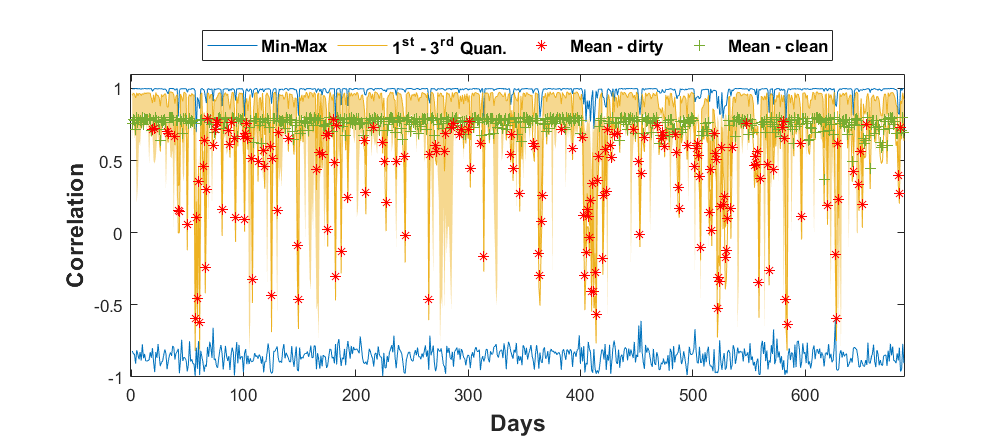

% Calculate the correlation of diurnal patterns 
correlation_diurnal_raw = corr(xDiurnal');
correlation_diurnal_raw(1:(size(xDiurnal,1)+1):end) = NaN; % set diagnoal elements into NaN, for calculation need

% calculate similarity distribution
binEdges= -1:0.2:1;
similarity_distribution_raw = nan(size(correlation_diurnal_raw,1),length(binEdges)-1);
for i = 1:size(similarity_distribution_raw,1)
    [similarity_distribution_raw(i,:), ~]=histcounts(correlation_diurnal_raw(i,:),binEdges,'Normalization','probability');
end

% calculate the simple statistics of similarity 
% 1- mean 2- min 3- first quantile 4- Median 5-Third quantile 6 - Maximum 
correlation_statistics_diurnal_raw = nan(size(correlation_diurnal_raw,1),6);
for i= 1:size(correlation_diurnal_raw,1)
    x = correlation_diurnal_raw(:,i);
    x = x(~isnan(x));
    correlation_statistics_diurnal_raw(i,:)  = [mean(x) min(x) quantile(x,[0.25 0.50 0.75]) max(x)];
end
% Figure to show simple statistics won't work 
figure('position',[0 0 800 350],'Units','centimeters');

ax1= plot(correlation_statistics_diurnal_raw(:,2),'-',"Color",[0 0.4470 0.7410]);
hold on;
ax2= plot(correlation_statistics_diurnal_raw(:,6),'-',"Color",[0 0.4470 0.7410]);
fill([1:688 fliplr(1:688)]',[correlation_statistics_diurnal_raw(:,5); fliplr(correlation_statistics_diurnal_raw(:,3))],...
    [0.9290 0.6940 0.1250],'FaceAlpha',0.5,'EdgeColor',"none");
ax3= plot(correlation_statistics_diurnal_raw(:,3),'-',"Color",[0.9290 0.6940 0.1250]);
ax4= plot(correlation_statistics_diurnal_raw(:,5),'-',"Color",[0.9290 0.6940 0.1250]);
temp = 1:688;
ax6= plot(temp(~data_label),correlation_statistics_diurnal_raw(~data_label,1),'+','Color',[0.4660 0.6740 0.1880]);
ax5= plot(temp(data_label),correlation_statistics_diurnal_raw(data_label,1),'*r');

xlim([-1,689]);
ylim([-1,1.1]);
xlabel('Days','FontSize',14,'FontWeight','bold');
ylabel('Correlation','FontSize',14,'FontWeight','bold');
hleglines = [ax1 ax3 ax5 ax6];
legend(hleglines,'Min-Max','1^s^t - 3^r^d Quan.','Mean - dirty','Mean - clean',...
    'FontSize',10,'FontWeight','bold','Location','northoutside','NumColumns',4);

clearvars -except xBOD data_label xDiurnal xLeachate similarity_distribution_raw correlation_statistics_diurnal_raw; 

### The implementation of Classification

This was accomplished by the *Statistics and Machine Learning Toolbox™ - Classification Learner. *The whole process is quite Tedious, therefore, the process was skipped, but it should easiler be reproduced by anyone who is familiar with this toolbox. The trained classifier is stored as ***trainClassifier.m ***

We here only provide the code that generates the best performance as in the paper, with stuck_index defined as below: 


$$\mathrm{SI}=\frac{\sum_{t=1}^n y\left(t\right)-y\left(t+1\right)}{n-1\;}$$


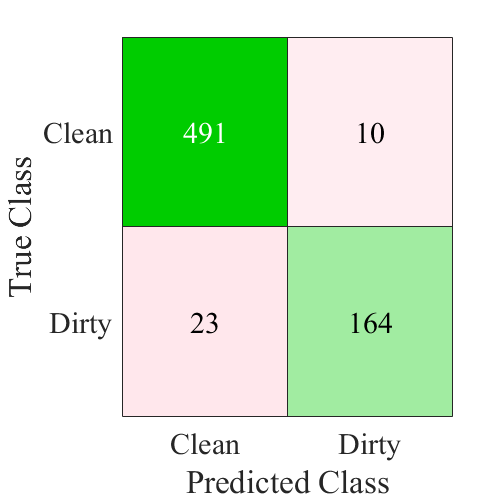

%Calcualte the stuck index 
stuck_idx = sum(diff(xBOD') == 0)/719;

% Train logistic Regression model with SI 
classification_set = [similarity_distribution_raw stuck_idx' ~data_label]; 
rng(0408);
warning('off');
[LogRegMdl,ValAcuracy]=trainClassifier(classification_set);
Classification_pred = LogRegMdl.predictFcn(classification_set(:,1:end-1));
warning('on'); 

% Extract the classification result in 
TP =[];
TN =[];
FP =[];
FN =[];
for i =1:length(Classification_pred)
    if (Classification_pred(i) == 0) && (~data_label(i) == 0)      % True positive
        TP = [TP;i];
    elseif (Classification_pred(i) == 1) && (~data_label(i) == 0)      % False negative
        FN = [FN;i];
    elseif Classification_pred(i) == 1 && (~data_label(i) == 1)      % True negative
        TN= [TN;i];
    else %Classification_pred(i) == 0 & (data_label(i) == 1)      % False positive
        FP= [FP;i];
    end
    
end
% plot results
[X,Y] = meshgrid(1:2,1:2);
Confusion_Matrix = [ length(TP)/(length(TP)+length(FP))  length(FN)/(length(FN)+length(TN)) ;
                     length(FP)/(length(TP)+length(FP))  length(TN)/(length(FN)+length(TN)) ];
figure('position',[0 0 400 400],'Units','centimeters');
true_label = cell(length(Classification_pred),1);
true_label(:) = {'Clean'};
true_label(data_label) = {'Dirty'} ;

pred_label = cell(length(Classification_pred),1);
pred_label(:) = {'Clean'};
pred_label(Classification_pred == 0) = {'Dirty'} ;

cm= confusionchart(true_label,pred_label);%,"Normalization","total-normalized"); %,'RowSummary',"row-normalized","ColumnSummary","column-normalized");
cm.DiagonalColor    = 	[0 0.8 0];
cm.OffDiagonalColor =   [1 0 0.2];
cm.FontSize = 18;
cm.FontName = 'Times New Roman';

clearvars -except xBOD data_label xDiurnal xLeachate similarity_distribution_raw correlation_statistics_diurnal_raw TN TP FN FP LogRegMdl stuck_idx; 

## Section 3 Data Validation 

### Mapping from sensor data to composite data 

Training on single GPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:00 |       177.38 |       185.28 |   15732.0850 |   17164.6250 |      1.0000e-04 |


|       2 |          10 |       00:00:01 |       178.39 |       175.42 |   15911.4824 |   15385.2471 |      1.0000e-04 |


|       4 |          20 |       00:00:01 |        78.92 |        51.02 |    3114.1602 |    1301.5769 |      1.0000e-04 |


|       5 |          30 |       00:00:01 |        55.60 |        45.99 |    1545.4817 |    1057.4381 |      1.0000e-04 |


|       7 |          40 |       00:00:01 |        58.86 |        51.19 |    1732.3308 |    1310.1870 |      1.0000e-04 |


|       9 |          50 |       00:00:01 |        43.50 |        49.43 |     946.2617 |    1221.8693 |      1.0000e-04 |


|      10 |          60 |       00:00:01 |        42.94 |        46.52 |     921.8574 |    1082.2811 |      1.0000e-04 |


|      12 |          70 |       00:00:02 |        44.68 |        45.74 |     998.2745 |    1045.9183 |      1.0000e-04 |


|      14 |          80 |       00:00:02 |        45.98 |        44.94 |    1057.3048 |    1009.8259 |      1.0000e-04 |


|      15 |          90 |       00:00:02 |        39.54 |        44.65 |     781.5879 |     996.9816 |      1.0000e-04 |


|      17 |         100 |       00:00:02 |        44.58 |        44.41 |     993.5237 |     986.1893 |      1.0000e-04 |


|      19 |         110 |       00:00:02 |        48.92 |        44.05 |    1196.7563 |     970.2273 |      1.0000e-04 |


|      20 |         120 |       00:00:02 |        46.16 |        43.76 |    1065.5424 |     957.6146 |      1.0000e-04 |


|      22 |         130 |       00:00:02 |        39.45 |        43.82 |     778.2825 |     959.9126 |      1.0000e-04 |


|      24 |         140 |       00:00:03 |        41.49 |        43.43 |     860.7552 |     943.2545 |      1.0000e-04 |


|      25 |         150 |       00:00:03 |        45.53 |        43.26 |    1036.4481 |     935.8883 |      1.0000e-04 |


|      27 |         160 |       00:00:03 |        42.95 |        42.79 |     922.3593 |     915.4763 |      1.0000e-04 |


|      29 |         170 |       00:00:03 |        39.18 |        42.96 |     767.4858 |     922.9113 |      1.0000e-04 |


|      30 |         180 |       00:00:03 |        42.95 |        42.48 |     922.3624 |     902.2386 |      1.0000e-04 |


|      32 |         190 |       00:00:03 |        40.53 |        42.30 |     821.5055 |     894.6854 |      1.0000e-04 |


|      34 |         200 |       00:00:03 |        39.16 |        41.81 |     766.6639 |     874.1496 |      1.0000e-04 |


|      35 |         210 |       00:00:04 |        37.98 |        41.88 |     721.1757 |     876.8264 |      1.0000e-04 |


|      37 |         220 |       00:00:04 |        45.49 |        41.40 |    1034.5106 |     856.9047 |      1.0000e-04 |


|      39 |         230 |       00:00:04 |        47.59 |        41.17 |    1132.4508 |     847.5630 |      1.0000e-04 |


|      40 |         240 |       00:00:04 |        41.46 |        40.96 |     859.4736 |     838.9361 |      1.0000e-04 |


|      42 |         250 |       00:00:04 |        33.15 |        40.83 |     549.6002 |     833.3641 |      1.0000e-04 |


|      44 |         260 |       00:00:04 |        34.71 |        40.53 |     602.2424 |     821.1555 |      1.0000e-04 |


|      45 |         270 |       00:00:05 |        40.92 |        40.40 |     837.0406 |     816.0964 |      1.0000e-04 |


|      47 |         280 |       00:00:05 |        39.27 |        40.04 |     770.9846 |     801.5225 |      1.0000e-04 |


|      49 |         290 |       00:00:05 |        36.90 |        39.81 |     680.6952 |     792.5731 |      1.0000e-04 |


|      50 |         300 |       00:00:05 |        36.78 |        39.50 |     676.2229 |     780.0887 |      1.0000e-04 |


|======================================================================================================================|


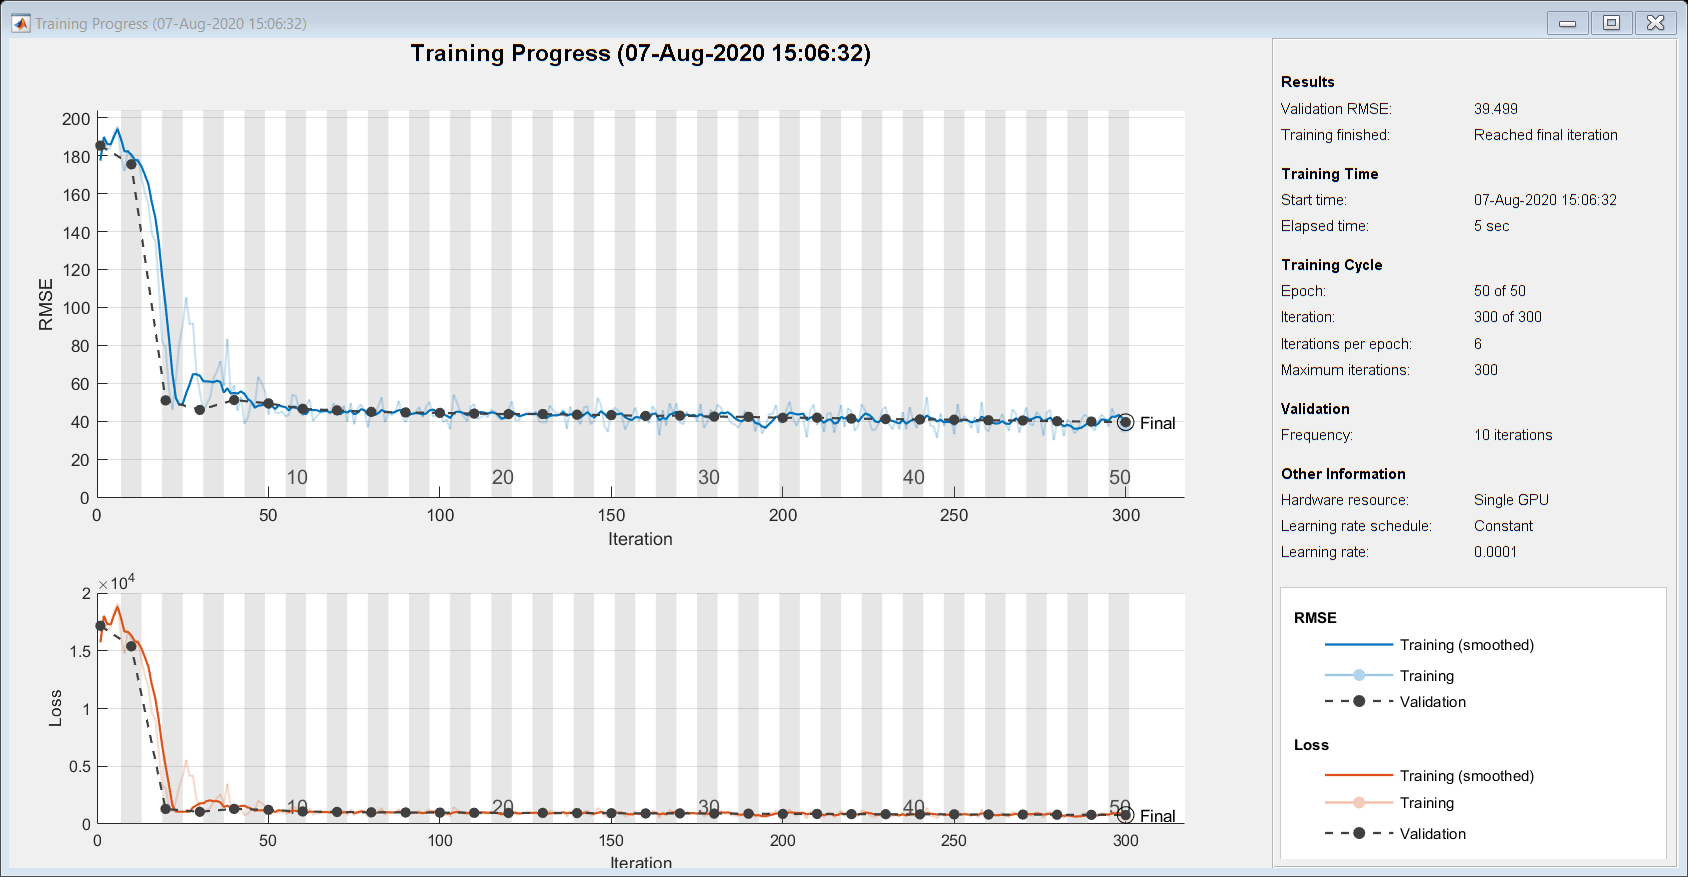

% Load composite BOD data 
load yBOD;
load xflow;
% Train deep NN work with Diurnal 
data_cube = nan(720,1,1,size(xDiurnal,1));

for i = 1:size(xDiurnal,1)
    data_cube(:,1,1,i) = xDiurnal(i,:);
end

data_cube = data_cube/440; % normalized by 500 mg/L to ensure all input are within [0,1];  
                     % The min-max between all results are around 436.
                     
XTrain  = data_cube(:,:,:,~data_label); % only subset the clean data for training 

 
YTrain  = yBOD(~data_label) ;
% Seed to ensure reproducity 
rng(0407);
% Separate Training and Testing set to measure overfitting issue. 
idx = randperm(size(XTrain,4),100);
XTest = XTrain(:,:,:,idx); % choose out testing set, which are 100 out of 501 (20%)
XTrain(:,:,:,idx) = [];          % delete validation set in the training X and Y
YTest = YTrain(idx);
YTrain(idx) = [];
% Neural Network Structure 
layers = [
    imageInputLayer([720 1 1])

    
    fullyConnectedLayer(24) 
    
    fullyConnectedLayer(1) 
    
    regressionLayer];


miniBatchSize  = 60;
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',50, ...
    'ValidationData',{XTest,YTest}, ...
    'ValidationFrequency',10, ...
    'Shuffle','every-epoch', ...
    'InitialLearnRate',1e-4, ...
    'Plots','training-progress');

net = trainNetwork(XTrain,YTrain,layers,options); % result are stored in net. 

#### Flow-proportional model 

clear i idx;
% Calculate Baseline model - flow weighted, y_hat  
xflow_mean = nanmean(xflow,1);
y_hat = xBOD *(xflow_mean'./sum(xflow_mean));

% NN prediction 
% Predict results on testing set
YTrain_nnpred = predict(net,XTrain);
Ytest_nnpred = predict(net,XTest);

% Figrue to validate dirty data not fitting quite well in the NN network model  
idx= 1:size(xBOD,1);
clean_id = idx(~data_label);
dirty_id = idx(data_label);

XDirty  = data_cube(:,:,:,dirty_id); % only subset the clean data for training 
YDirty  = yBOD(dirty_id);
YDirty_pred = predict(net, XDirty);

#### Figure 6 -Creation 

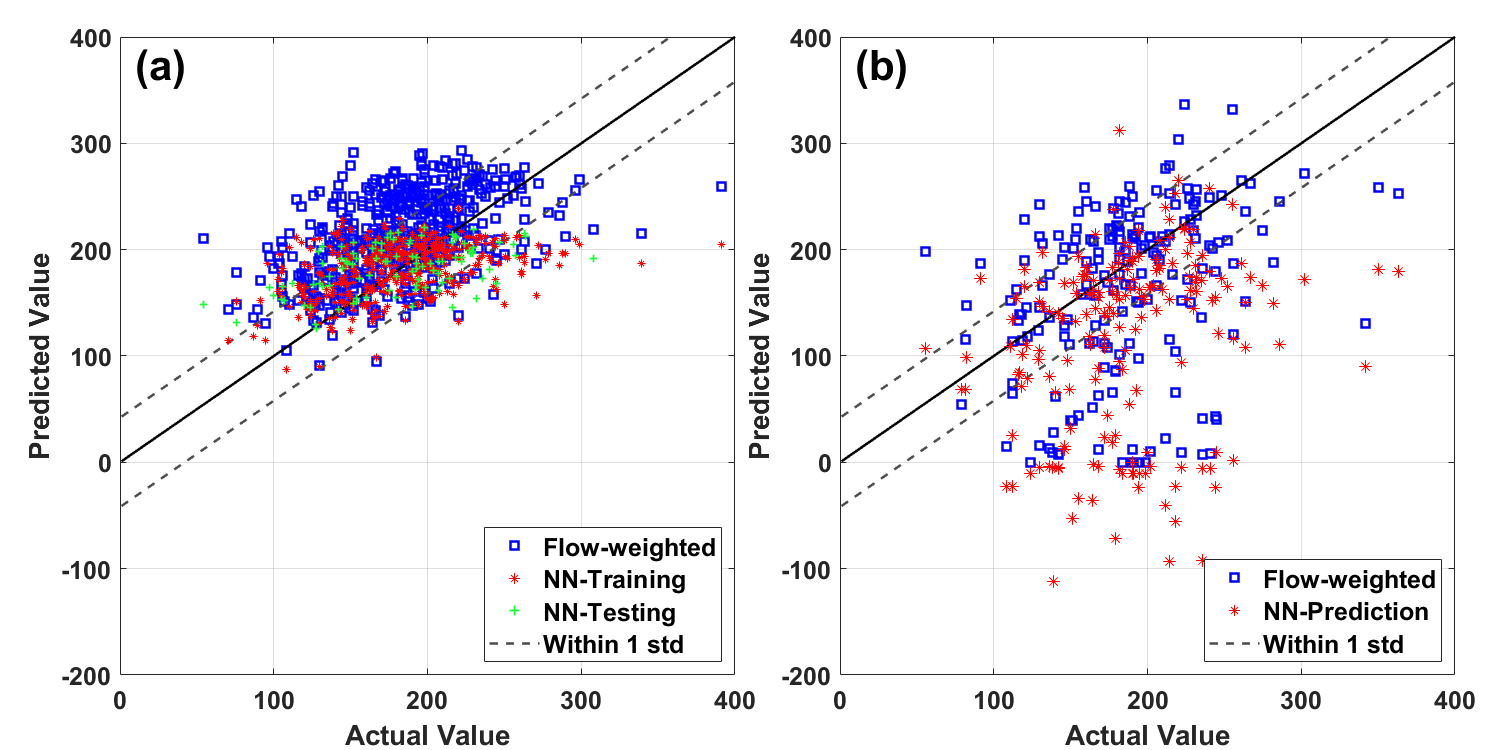

% Combine plot of both dirty and clean
figure('position',[100 100 1200 600],'Units','points');

% Clean
ax1 = axes('position',[0.08,0.1,0.41,0.85]);
actual = yBOD(~data_label); % Only use the clean labeled data
pred= y_hat(~data_label);

p1=scatter(actual,pred,'Marker','square','MarkerEdgeColor','blue','LineWidth',1.5);
hold on;
plot(1:1000,1:1000,'-k','LineWidth',1.5);
plt4 = plot(1:1000,(1:1000)+42,'--k','LineWidth',1.5,"Color",[0.3 0.3 0.3]);
plot(1:1000,(1:1000)-42,'--k','LineWidth',1.5,"Color",[0.3 0.3 0.3]);
hold off;
box on;
grid on;
xlabel('Actual Value','FontSize',15,'FontWeight','bold');
ylabel('Predicted Value','FontSize',15,'FontWeight','bold');
hold on;
p2 = scatter(YTrain,YTrain_nnpred ,'*r','SizeData',20,'LineWidth',0.5);
hold on;
p3 = scatter(YTest,Ytest_nnpred,'+','SizeData',20,'LineWidth',1,'MarkerEdgeColor',[0.1 1 0.2]);
xlim([0 400]);
ylim([-200 400]);



% extract the handles that require legend entries
hleglines = [p1(1) p2 p3 plt4];
legend(hleglines,'Flow-weighted','NN-Training','NN-Testing','Within 1 std',...
    'FontSize',15,'FontWeight','bold' ,'location','southeast','numcolumns',1);

text(ax1,10,375,'(a)',"FontWeight","bold",'FontSize',25);
 
set(ax1,'fontsize',15,'FontWeight','bold')

% Dirty 
ax2 = axes('position',[0.56,0.1,0.41,0.85]);

actual = yBOD(data_label); % Only use the clean labeled data
pred= y_hat(data_label);

plt1=scatter(actual,pred,'Marker','square','MarkerEdgeColor','blue','LineWidth',1.5);
hold on; 
plot(1:1000,1:1000,'-k','LineWidth',1.5);
plt4= plot(1:1000,(1:1000)+42,'--k','LineWidth',1.5,"Color",[0.3 0.3 0.3]);
plot(1:1000,(1:1000)-42,'--k','LineWidth',1.5,"Color",[0.3 0.3 0.3]);
hold off;

box on;
grid on;
xlabel('Actual Value','FontSize',15,'FontWeight','bold');
ylabel('Predicted Value','FontSize',15,'FontWeight','bold');

hold on;
plt2 = scatter(YDirty,YDirty_pred ,'*r','SizeData',50,'LineWidth',0.5);

xlim([0 400]);
ylim([-200 400]);

% extract the handles that require legend entries
hleglines = [plt1 plt2 plt4];
legend(hleglines,'Flow-weighted','NN-Prediction','Within 1 std',...
    'FontSize',15,'FontWeight','bold' ,'location','southeast','numcolumns',1);


hold off;
text(ax2,10,375,'(b)',"FontWeight","bold",'FontSize',25);
set(ax2,'fontsize',15,'FontWeight','bold');

#### Figure 7 -Creation

**Note:  **

The therapy part is just a preliminary trial, and the **gapFilling.m** is not well developed to a practical phase. The whole system is still under development. This portion simply serves as a proof of concept. 

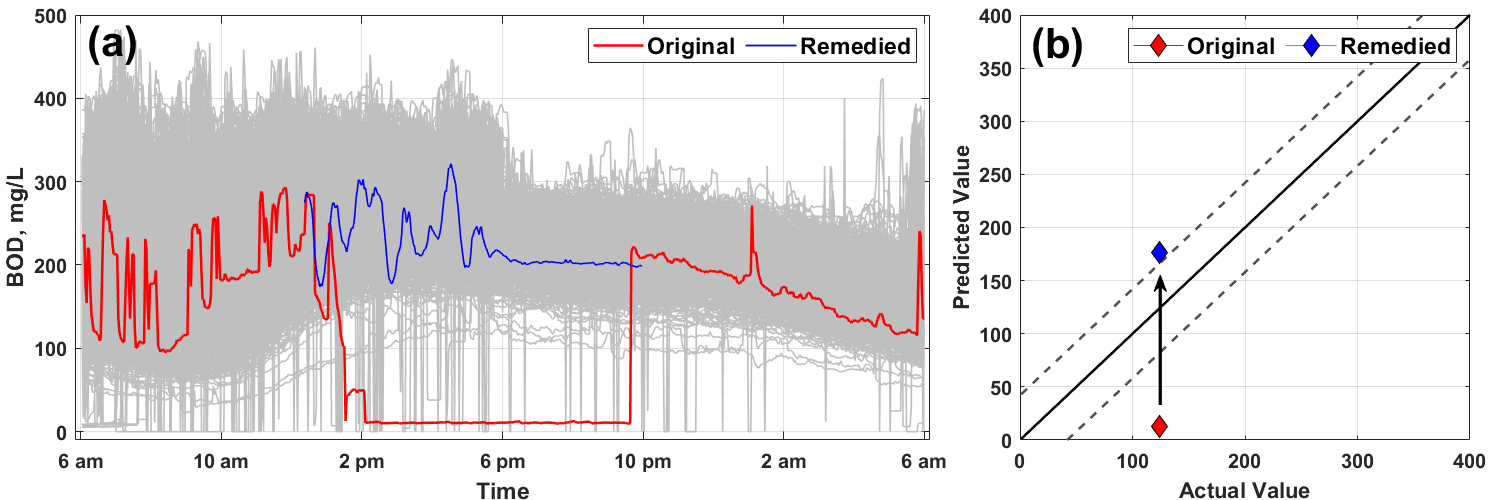

% Select one special case of dirty signals 
dirty_id_example = 265 ;    
temp = xBOD(dirty_id_example,:);
ra = 190:480;
temp(ra)=NaN;
refill = gapFilling(temp,xBOD(~data_label,:),20);
refill_D = separatePattern(refill);
refill([1:ra(1) ra(end):end])=nan; 

temp_nnpred = predict(net,data_cube(:,:,:,dirty_id_example));

refill_D_x =nan(720,1,1,1);
refill_D_x(:,1,1,1) = refill_D/440;

refill_nnpred = predict(net,refill_D_x(:,1,1,1));

% plot results 
fig = figure('position',[0.1 0.1 1200 400],'Units','points','color','w');

% The time series figure
ax1 = axes('position',[0.05,0.12,0.57,0.85]);
L1 = plot(1:720,xBOD(~data_label,:)','color',[0.75 0.75 0.75],'LineWidth',1);
hold on;
L2 = plot(1:720,xBOD(dirty_id_example,:),'color',[1 0 0],'LineWidth',1.5);
L3 = plot(refill,'b','LineWidth',1);

% legend Setting
% extract the handles that require legend entries
hleglines = [L2 L3 ];
legend(hleglines,'Original','Remedied','FontSize',14,'FontWeight','bold',...
    'NumColumns',3);

% X&Y ticks
ylim([-10,500]);
xlim([-5,725]);
set(gca,'XTick',linspace(0,720,7),'XTickLabel',{'6 am','10 am','2 pm','6 pm','10 pm','2 am','6 am'},...
    'FontWeight','bold');
set(gca,'YTick',linspace(0,500,6));
set(gca,'FontSize',12)
% X & Y labels
xlabel('Time','FontSize',14,'FontWeight','bold');
ylabel('BOD, mg/L','FontSize',14,'FontWeight','bold');
grid on;
hold off;

% Remedied data 
ax2 = axes('position',[0.68,0.12,0.3,0.85]);
plot(1:1000,1:1000,'-k','LineWidth',1.5);
hold on;
plt1= plot(1:1000,(1:1000)+42,'--k','LineWidth',1.5,"Color",[0.3 0.3 0.3]);
plot(1:1000,(1:1000)-42,'--k','LineWidth',1.5,"Color",[0.3 0.3 0.3]);


plt3= plot(yBOD(256),temp_nnpred,'marker','diamond',"MarkerSize",10,'MarkerEdgeColor','k',"MarkerFaceColor","r");

plt4= plot(yBOD(256),refill_nnpred,'marker','diamond',"MarkerSize",10,'MarkerEdgeColor','k',"MarkerFaceColor","b");

box on;
grid on;
xlabel('Actual Value','FontSize',15,'FontWeight','bold');
ylabel('Predicted Value','FontSize',15,'FontWeight','bold');

hold on;


xlim([0 400]);
ylim([0 400]);

% % extract the handles that require legend entries
% hleglines = [plt1 plt2 plt4];
% legend(hleglines,'Flow-weighted','NN-Prediction','Within 1 std',...
%     'FontSize',15,'FontWeight','bold' ,'location','southeast','numcolumns',1);
hold off;
text(ax2,10,375,'(b)',"FontWeight","bold",'FontSize',25);
set(ax2,'fontsize',12,'FontWeight','bold')
text(ax1,5,470,'(a)',"FontWeight","bold",'FontSize',25);
annotation("arrow",[0.7735 0.7735],[0.19 0.45],'LineWidth',2);

hleglines = [plt3 plt4 ];
legend(hleglines,'Original','Remedied','FontSize',14,'FontWeight','bold',...
    'NumColumns',3);